Question 01.

disp("Question 01.")

Question 01.



% Defining symbolic variables

syms x y k

% Finding critical points

eqns1 = [(x-4*y) == 0, (-x+y) == 0];
eqns1

$$eqns1 = \left(\begin{array}{cc} x-4\,y=0 & y-x=0 \end{array}\right)$$

[x1 y1] = solve(eqns1, [x y]);
[x1 y1]

$$ans = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


% Finding matrix for eigenvalues

eqns2 = ((+1-k)*(+1-k))-((-1)*(-4)) == 0;
eqns2

$$eqns2 = {\left(k-1\right)}^{2}-4=0$$

k = solve(eqns2, k);
k

$$k = \left(\begin{array}{c} -1\\ 3 \end{array}\right)$$

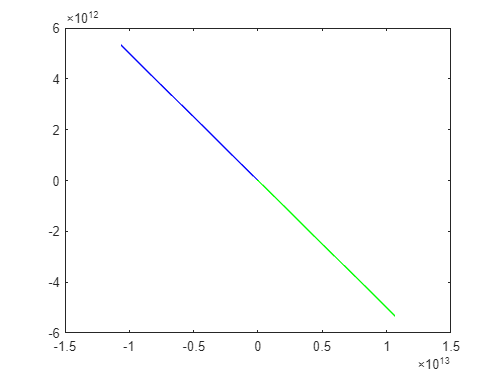


% Critical point is stable spiral point since eigenvalues have negative real part

% Plotting phase plane trajectories

for a = -0.5:0.1:0.5
    Y0 = [-1;a];
    [T,Y] = ode45(@eqns3,[0 10],Y0);
    plot(Y(:,1),Y(:,2),'blue -')
    hold on
end

for a = -0.5:0.1:0.5
    Y0 = [1;a];
    [T,Y] = ode45(@eqns3,[0 10],Y0);
    plot(Y(:,1),Y(:,2),'green -')
    hold on
end


% Defining function for equations


function F = eqns3(t,y)
    F=[y(1)-4*y(2); -y(1)+y(2)];  
end
